clear; clc; close all;
mpt_init; yalmip('clear');

MPT searches for solvers on the path ...
 
 LINPROG ............................................ linprog.m 
 QUADPROG .......................................... quadprog.m 
 GLPK .................................................. glpkcc 
 CDD ................................................... cddmex 
 MOSEK ............................................... mosekopt 
 LCP ...................................................... lcp 
 SEDUMI .............................................. sedumi.m 
 PLCP .............................................. mpt_plcp.m 
 MPQP .............................................. mpt_mpqp.m 
 MPLP .............................................. mpt_mplp.m 
 ENUMPLCP ..................................... mpt_enum_plcp.m 
 ENUMPQP ....................................... mpt_enum_pqp.m 
 RLENUMPQP ..................................... mpt_enum_pqp.m 

MOSEK Version 11.0.27 (Build date: 2025-7-30 14:30:38)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform

addpath(fileparts(fileparts(which('optimizer'))),'-begin'); rehash toolboxcache;

rng(1e4);

# Problem 

%% ========================================================================
% ACC: CLF-CBF-QP teacher + hard interface (deployable) for Cert/CertNet
%
% State:
%   xi = [D; v; vL] in R^3
%   D  : distance to lead vehicle
%   v  : ego speed
%   vL : lead speed
%
% Extra learner input:
%   eta = vdes (desired speed)
%   learner input z = [xi; vdes] in R^4
%
% Control:
%   u (scalar acceleration)
%
% Dynamics (Euler discretization):
%   D_{k+1} = D_k + Ts*(vL_k - v_k)
%   v_{k+1} = v_k + Ts*(u_k - cd*v_k)
%
% Hard interface (deployment constraint set):
%   u in U(xi) := { u | G*u <= h - S*xi }
%   We include:
%     - input bounds
%     - state bounds (k)
%     - safety CBF at k and k+1
%     - next-step bounds (k+1)
%
% Baselines:
%   (1) QP teacher: CLF (soft) + CBF (hard) + bounds
%   (2) PureNN: regression z -> u
%   (3) NN+Proj: project u_hat onto U(xi)
%   (4) Cert / CertNet: certified candidate query + fixed mixing
% ========================================================================

%% ===================== (0) Parameters (clean) =====================
[Ts, eps_feas] = deal(0.02, 1e-5); Ts_us = Ts*1e6;
[cd, tau] = deal(0.05, 1.8);

g = 9.81; [umin, umax] = deal(-0.6*g, 0.3*g);

[Dmin, Dmax] = deal(0, 100);
[vmin, vmax] = deal(15, 30);
[vLmin, vLmax] = deal(20, 25);

%% ===================== (1) Hard interface: build (G,S,h) s.t. G*u <= h - S*xi =====================
% xi = [D; v; vL], u scalar
[G,S,h] = deal([],[],[]);

% ------------------------------------------------------------------------
% (A) Input bounds: u in [umin, umax]
%   u <= umax         =>  1*u <= umax  - 0*xi
%   u >= umin         => -1*u <= -umin - 0*xi
% ------------------------------------------------------------------------
G = [G;  1]; S = [S; 0 0 0]; h = [h;  umax];
G = [G; -1]; S = [S; 0 0 0]; h = [h; -umin];

% ------------------------------------------------------------------------
% (B) State bounds at k (u-independent, encoded via G=0 rows)
%   D in [Dmin,Dmax], v in [vmin,vmax], vL in [vLmin,vLmax]
% ------------------------------------------------------------------------
G = [G; 0]; S = [S;  1  0  0]; h = [h;  Dmax];
G = [G; 0]; S = [S; -1  0  0]; h = [h; -Dmin];

G = [G; 0]; S = [S;  0  1  0]; h = [h;  vmax];
G = [G; 0]; S = [S;  0 -1  0]; h = [h; -vmin];

G = [G; 0]; S = [S;  0  0  1]; h = [h;  vLmax];
G = [G; 0]; S = [S;  0  0 -1]; h = [h; -vLmin];

% ------------------------------------------------------------------------
% (C) Safety CBF (your original two constraints)
%   hk   = D - tau*v >= 0
%   hk1  = D1 - tau*v1 >= 0
%
% (C1) hk >= 0:
%   0*u <= D - tau*v  => 0*u <= 0 - [-1, tau, 0]*xi
% ------------------------------------------------------------------------
G = [G; 0]; S = [S; -1, tau, 0]; h = [h; 0];

% ------------------------------------------------------------------------
% (C2) hk1 >= 0:
%   D1 = D + Ts*(vL - v)
%   v1 = (1 - Ts*cd)*v + Ts*u
%   hk1 = D1 - tau*v1 >= 0
%   ==> tau*Ts*u <= D + Ts*vL - (tau + Ts - tau*Ts*cd)*v
%   Put in G*u <= h - S*xi:
%     (tau*Ts)*u <= 0 - [ -1, (tau+Ts-tau*Ts*cd), -Ts ]*xi
% ------------------------------------------------------------------------
G = [G;  tau*Ts];
S = [S; -1, (tau + Ts - tau*Ts*cd), -Ts];
h = [h;  0];

% ------------------------------------------------------------------------
% (D) Next-step bounds at k+1 (optional but included in your script)
%   D1 in [Dmin,Dmax], v1 in [vmin,vmax]
%
% D1 = D + Ts*(vL - v):
%   D1 <= Dmax  => 0*u <= Dmax - [1, -Ts, Ts]*xi
%   D1 >= Dmin  => 0*u <= -Dmin - [-1, Ts, -Ts]*xi
%
% v1 = (1-Ts*cd)*v + Ts*u:
%   v1 <= vmax  => Ts*u <= vmax - [0, (1-Ts*cd), 0]*xi
%   v1 >= vmin  => -Ts*u <= -vmin - [0, -(1-Ts*cd), 0]*xi
% ------------------------------------------------------------------------
G = [G; 0];  S = [S;  1, -Ts,  Ts];  h = [h;  Dmax];
G = [G; 0];  S = [S; -1,  Ts, -Ts];  h = [h; -Dmin];

G = [G;  Ts]; S = [S; 0,  (1 - Ts*cd), 0]; h = [h;  vmax];
G = [G; -Ts]; S = [S; 0, -(1 - Ts*cd), 0]; h = [h; -vmin];

# Baseline Construction

## Optimization baseline 

%% ===================== (2) Optimization baseline (Teacher): CLF-CBF-QP =====================
% QP variables:
%   u    : accel
%   del  : CLF slack (>=0)
%   kappa,s0 : auxiliary knobs (as in your original script)
%
% Params:
%   xi   = [D;v;vL]
%   vdes
%
% Constraints:
%   - input bounds + v1 bounds
%   - HARD hk1 >= 0
%   - SOFT stronger CBF hk1 >= (1-kappa)*hk + s0  (as written)
%   - CLF decrease (soft) via del
%
% Output:
%   OPbase_acc : optimizer({xi,vdes}) -> u
% ------------------------------------------------------------------------
ops = sdpsettings('solver','mosek','verbose',0);

[u, del] = deal(sdpvar(1,1), sdpvar(1,1));
[kappa, s0] = deal(sdpvar(1,1), sdpvar(1,1));

[xi, vdes] = deal(sdpvar(3,1), sdpvar(1,1));
[D, v, vL] = deal(xi(1), xi(2), xi(3));

D1 = D + Ts*(vL - v);
v1 = (1 - Ts*cd)*v + Ts*u;

tau = 1.8;
hk  = D  - tau*v;
hk1 = D1 - tau*v1;

Vk  = (v  - vdes)^2;
Vk1 = (v1 - vdes)^2;

alphaV = 0.20;

C = [];

C = [C, umin <= u, u <= umax];
C = [C, vmin <= v1, v1 <= vmax];

s0tmp = 0;
C = [C, del >= 0];
C = [C, 0 <= kappa, kappa <= 1];
C = [C, s0 >= 0, s0 <= s0tmp];

C = [C, hk1 >= 0];                    % HARD CBF
C = [C, hk1 >= (1 - kappa)*hk + s0];  % STRONGER CBF (as in your script)
C = [C, (Vk1 - Vk) <= -alphaV*Vk + del];

u_ref = 0.8*(vdes - v) + cd*v;

[w_u, w_del] = deal(1.0, 1e2);
[w_r, w_kappa, w_s0] = deal(1e6, 1e3, 1e3);

J = w_u*(u - u_ref)^2 + w_del*del + w_kappa*(kappa - 0.8)^2 + w_s0*(s0 - s0tmp)^2;

OPbase_acc = optimizer(C, J, ops, {xi, vdes}, u);

## Pure Net

%% ===================== (4) PureNN: z=[D;v;vL;vdes] -> u =====================
ni = 4; no = 1;
PureNNlayers = build_pureNN_(ni, no, [64,64]);

## Projection

%% ===================== (4) NN+Proj baseline: project u_hat onto U(xi) =====================
% Projection:
%   u_proj(xi,u_hat) = argmin_u (u-u_hat)^2  s.t.  G*u <= h - S*xi
ops_prj = sdpsettings('solver','mosek','verbose',0);

[u_prj, xi_p, u_hat] = deal(sdpvar(1,1), sdpvar(3,1), sdpvar(1,1));
Cprj = (G*u_prj <= h - S*xi_p);
Jprj = (u_prj - u_hat)^2;

OPNNProj = optimizer(Cprj, Jprj, ops_prj, {xi_p, u_hat}, u_prj);

## Certifier & CertNet

%% ===================== (5) Certifier & CertNet =====================
% Hard interface:
%   u in U(xi) := { u | G*u <= h - S*xi }
cfg_cert = struct();
cfg_cert.opt = struct('use_scale',true,'tol_build',1e-8,'rcond_thr',1e-12,'tol_query',1e-9,'use_cacheAct',1);

OPCert = Cert(G, h, S, cfg_cert);

nLaws=5


OPCertNet = Certnet(OPCert, [], ni);

# Training of pureNN & CertNet

## Generate Training Data

%% ===================== (6) Training data (match your current sampling) =====================
% Supervision:
%   XTrain: [D, v, vL, vdes]
%   YTrain: u_teacher = OPbase_acc{xi, vdes}
Ntrain = 20000;
[Nepi, Tepi] = deal(100, Ntrain/100); %#ok<NASGU>
assert(mod(Ntrain,Nepi)==0);

[XTrain, YTrain] = deal(zeros(Ntrain,ni), zeros(Ntrain,no));
Ph = Polyhedron([S,G],h); %#ok<NASGU>

for i = 1:Ntrain
    vk = vmin + (vmax - vmin)*rand;
    vLk = vLmin + (vLmax - vLmin)*rand;
    vdesk = 20 + randi(10);
    Dk = tau*vk + 30*rand;

    xi_k = [Dk; vk; vLk];
    uk = OPbase_acc{xi_k, vdesk};

    XTrain(i,:) = [Dk, vk, vLk, vdesk];
    YTrain(i,:) = uk;
end

p = randperm(Ntrain); XTrain = XTrain(p,:); YTrain = YTrain(p,:);
fprintf('[DATA] XTrain=%dx%d, YTrain=%dx%d\n', size(XTrain,1),size(XTrain,2), size(YTrain,1),size(YTrain,2));

[DATA] XTrain=20000x4, YTrain=20000x1


## Active cache 

%% ===================== (7) Active cache build (Act) =====================
% Stage A: vertices(x0,u0) identification
% Stage B: api_check_cover_cacheAct_(do_augment=1) augmentation
OPCertNet.cert.opt_hot.update_cacheAct = true;
OPCertNet.cert.opt_hot.use_cacheAct = true;

for i = 1:size(XTrain,1)
    x0 = XTrain(i,:).'; u0 = YTrain(i,:).';
    OPCertNet.cert.vertices(x0, u0);
end

cfg = struct(); cfg.do_augment = 1;
[isCovered, ~] = OPCertNet.cert.api_check_cover_cacheAct_(cfg); 
%% Print coverage status
if isCovered
    fprintf('[Act] Coverage: FULL (cacheAct covers the target X-domain)\n');
else
    fprintf('[Act] Coverage: NOT FULL (some X not covered by cacheAct)\n');
end

[Act] Coverage: FULL (cacheAct covers the target X-domain)



%% Freeze updates
OPCertNet.cert.opt_hot.update_cacheAct = 0;

fprintf('n_{LFull}: %d, n_{LAct}: %d\n', numel(OPCertNet.cert.cache.idList), numel(OPCertNet.cert.cacheAct.idList));

n_{LFull}: 5, n_{LAct}: 5


## Training of PureNN

%% ===================== (8) PureNN training (normalize + Adam) =====================
[epochs,batch,lr] = deal(30, 1024, 1e-2);

muX = mean(XTrain,1); sigX = std(XTrain,0,1); sigX(sigX<1e-12) = 1;
XTrainN = (XTrain - muX) ./ sigX;

opts = trainingOptions('adam','MaxEpochs',epochs,'MiniBatchSize',batch,'InitialLearnRate',lr,'Shuffle','every-epoch','Verbose',false);
PureNN = trainNetwork(XTrainN, YTrain, PureNNlayers, opts);

OPpureNNAlg = net_to_alg_(PureNN);
OPpureNNAlg.muX = single(muX(:));
OPpureNNAlg.sigX = single(sigX(:));

## Training of CertNet

% For comparison
OPCertNet_raw = getArrayFromByteStream(getByteStreamFromArray(OPCertNet));  % BEFORE training

%% ===================== (9) CertNet training =====================
cfg = struct();
[cfg.epochs, cfg.lr, cfg.batch] = deal(epochs, lr, batch);
[cfg.g_floor, cfg.g_max, cfg.use_t_norm] = deal(1e-9, inf, 1);

OPCertNet.train(XTrain, YTrain, cfg);

[TRAIN]   1/ 30 | t=3.29 s | loss=5.922e-01 | lr=0.01
[TRAIN]   2/ 30 | t=0.331 s | loss=4.867e-02 | lr=0.01
[TRAIN]   3/ 30 | t=0.324 s | loss=1.947e-02 | lr=0.01
[TRAIN]   4/ 30 | t=0.343 s | loss=1.284e-02 | lr=0.01
[TRAIN]   5/ 30 | t=0.331 s | loss=1.027e-02 | lr=0.01
[TRAIN]   6/ 30 | t=0.373 s | loss=9.005e-03 | lr=0.01
[TRAIN]   7/ 30 | t=0.342 s | loss=8.207e-03 | lr=0.01
[TRAIN]   8/ 30 | t=0.364 s | loss=6.801e-03 | lr=0.01
[TRAIN]   9/ 30 | t=0.353 s | loss=6.475e-03 | lr=0.01
[TRAIN]  10/ 30 | t=0.377 s | loss=5.744e-03 | lr=0.01
[TRAIN]  11/ 30 | t=0.347 s | loss=5.480e-03 | lr=0.01
[TRAIN]  12/ 30 | t=0.319 s | loss=5.564e-03 | lr=0.01
[TRAIN]  13/ 30 | t=0.352 s | loss=4.977e-03 | lr=0.01
[TRAIN]  14/ 30 | t=0.348 s | loss=4.668e-03 | lr=0.01
[TRAIN]  15/ 30 | t=0.355 s | loss=4.533e-03 | lr=0.01
[TRAIN]  16/ 30 | t=0.301 s | loss=4.403e-03 | lr=0.01
[TRAIN]  17/ 30 | t=0.382 s | loss=4.474e-03 | lr=0.01
[TRAIN]  18/ 30 | t=0.312 s | loss=4.248e-03 | lr=0.01
[TRAIN]  19

# Test

% ===================== ACC: pack + warmup + test + report =====================
maxNumCompThreads(1);
pack = struct();

[pack.nTest, pack.Ts, pack.Ts_us, pack.eps_feas] = deal(1500, Ts, Ts_us, eps_feas);
[pack.cd, pack.tau] = deal(cd, tau);
[pack.umin, pack.umax, pack.vmin, pack.vmax] = deal(umin, umax, vmin, vmax);
[pack.G, pack.S, pack.h] = deal(G, S, h);

pack.xi0 = [81; 18; 20];

[pack.VdesTest, pack.VLTest] = deal(25*ones(pack.nTest,1), 20*ones(pack.nTest,1));

[pack.OPbase_acc, pack.OPpureNNAlg, pack.OPNNProj, pack.OPCertNet] = deal(OPbase_acc, OPpureNNAlg, OPNNProj, OPCertNet);

% ---- add an untrained CertNet (same cert, fresh NN params; plot-only) ----
pack.OPCertNet_raw = OPCertNet_raw;

% ---- timed closed-loop ----
out = acc_test_closedloop_(pack);


% ---- report (ignores plot-only by default) ----
Rep = acc_report_(out);
fprintf('%s\n', Rep.lines{:});

==================== ACC REPORT (CLOSEDLOOP) ====================
Ts = 20000us | eps_feas = 1.0e-05 | nTest = 1500

Columns: time_us(mean/p50/p99) | occ(mean/p99) | miss_rate | iface(vmax/rate) | hk1<0(rate) | J(mean/p95)
---------------------------------------------------------------------------------------------------------------
Method       | time_us            | occ           | miss      | iface            | hk1<0     | J             
---------------------------------------------------------------------------------------------------------------
Opt          |   897.3/ 859.1/1425.4 |  0.045/ 0.071 |    0.00% |  7.11e-15/  0.00% |    0.00% |  1.65e+01/ 2.52e+01
NN           |    17.7/  15.6/  37.8 |  0.001/ 0.002 |    0.00% |  1.09e+02/ 66.27% |   66.27% |  2.27e+00/ 1.62e+01
NN+Proj      |   800.6/ 812.7/1449.4 |  0.040/ 0.072 |    0.00% |  3.36e-06/  0.00% |    0.00% |  1.65e+01/ 2.70e+01
CertNet      |    81.2/  72.1/ 168.2 |  0.004/ 0.008 |    0.00% |  1.06e-09/  0.00% |    0.00

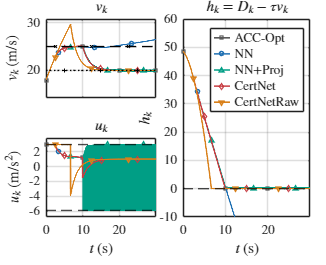

% ---- plot (will INCLUDE plot-only) ----
figure(1); clf;
pack.outdir = 'Figures';
pack.export_name = 'sim_ACC';
pack.export_eps = true;
acc_plot_(out, pack);

%% ===================== SAVE WORKSPACE VARIABLES (NO REBUILD) =====================
save_dir = 'C:\Users\12775\Box\jliao\m-certified-net';
if ~exist(save_dir,'dir'), mkdir(save_dir); end
stamp = datestr(now,'yyyy-mm-dd_HHMMSS');
save_path = fullfile(save_dir, ['ACC_vars_' stamp '.mat']);

vars = { ...
    'Ts','Ts_us','eps_feas','cd','tau','g','umin','umax','vmin','vmax','vLmin','vLmax','Dmin','Dmax', ...
    'G','S','h','Ph', ...
    'cfg_cert','OPCert','OPCertNet','OPCertNet_raw', ...
    'OPbase_acc','OPNNProj','OPpureNNAlg', ...
    'Ntrain','XTrain','YTrain','muX','sigX', ...
    'pack','out','Rep' ...
};

try
    save(save_path, vars{:}, '-v7.3');
    fprintf('[SAVE] wrote: %s\n', save_path);
catch ME
    fprintf(2,'[SAVE] FAILED: %s\n', ME.message);
    fprintf(2,'[SAVE] If file is too large, try removing XTrain/YTrain or out.\n');
end

[SAVE] wrote: C:\Users\12775\Box\jliao\m-certified-net\ACC_vars_2026-02-21_103921.mat
